# Lab work C

clear all
close all
lab_work_C_init_routine;

## Case 1: you are allowed to make use of the measurement in h1 and h2

lab_work_C_preparing_the_model;

p_mf = function_handle with value:
    @(u)u.*9.301350851526658-u.^2.*8.172784353877083e-1+u.^3.*2.906801569971661e-2+1.237853766511371e+1



% *** Checking the order of the system ***

% Order 0? No.
% Order 1? No.
dh = jacobian(h,x)*dx;
% Order 2? Yes.
ddh = jacobian(dh,x)*dx;

% Function to obtain the state xi from x, so xi = T(x)
T = [h;dh];
T_mf = matlabFunction(T);
% The reasoning is this...
% u_bar = k(xi,r)
syms r;

pole1 = -0.05;
pole2 = -0.075;
L = conv([1 -pole1],[1 -pole2]);
L = flip(L(2:end));

Lr = L(1);

k = solve(ddh==(-L*T+Lr*r),u_bar);
k_mf = matlabFunction(k);

% *** Simulation ***
sim_output_sample_time = 1;
sim_time = 500;

sim_r = cm2V_mf(10);
sim("feedback_linearization_sim",sim_time);

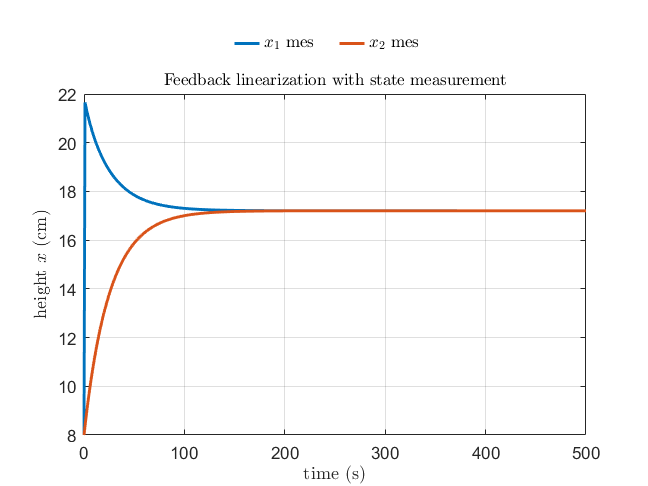

load("Results\sim_result_case_1_model");

figure();
plot(sim_result_case_1_model);
xlim([0 sim_time]);
hold on;
auto_plot('Feedback linearization with state measurement',...
        '$x_1$ mes|$x_2$ mes','time (s)|height $x$ (cm)');

saveas(gcf,'Plots/case_1_model.m');

## Case 2: you are not allowed to make use of the measurement in h1, but the measurement from h2 should be used.

% Stuff has been copied from the lab_work_A experience
sim_u = u0_8cm;
sim("feedback_linearization_kalman_filter_sim",sim_time);

Error due to
multiple causes.

Caused by:
    Error using
    lab_work_C
        Simulink
    cannot
    determine
    sizes and/or
    types of the
    outputs for
    block
    'feedback_linearization_kalman_filter_sim/Subsystem/Subsystem/MATLAB
    Function' due
    to errors in
    the block
    body, or
    limitations of
    the underlying
    analysis. The
    errors might
    be inaccurate.
    Fix the
    indicated
    errors, or
    explicitly
    specify sizes
    and/or types
    for all block
    outputs.


    Error using
    lab_work_C
        Error in
    port widths or
    dimensions.
    '


load("Results\sim_result_case_2_model");

figure();
plot(sim_result_case_2_model);
hold on;
auto_plot('Feedback linearization with state estimation',...
        '$x_1$ kal|$x_2$ kal','time (s)|height $h$ (cm)');
saveas(gcf,'Plots/case_2_feedback_linearization.m');

% Comparison
figure();
plot(sim_result_case_2_model);
hold on;
plot(sim_result_case_1_model,'--');
xlim([0 sim_time]);
auto_plot('Feedback linearization with state estimation',...
        '$x_1$ kal|$x_2$ kal|$x_1$ mes|$x_2$ mes','time (s)|height $h$ (cm)');
saveas(gcf,'Plots/case_1_2_comparison_model.m');